Problem 1

a) Generate R = 5 bootstrap resamples from y. 

b) Use your bootstrap resamples to estimate the bias of $s^2$

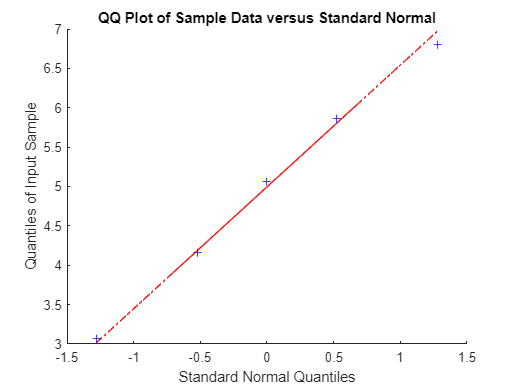

y = [1,3,2,7,5,6];
theta_hat = 5.6; %To estimate the variance of Y ~ F
% The TRUE parameter to estimate is theta = t(F) where t(·) = Var(·)
% We will use theta_hat = s(F_hat) or theta_hat = s(y) in this case with
% s(·) = (1/(n-1))*sum((y-y_mean)^2)-->Sample Variance
n = size(y,2);
R = 5;
theta_repl= zeros(1, R);
rand('state', 1);
for i=1:R
    rs_indx = ceil(n*rand(1,n));
    Y_boot = y(rs_indx);
    theta_repl(i) = var(Y_boot);
end
qqplot(theta_repl); % No refusem normalitat.

c) Use your bootstrap resamples to estimate a 95% confidence interval for σ^2.

% usaremos student's t porque al tener tan pocas muestras no podremos
% rechazar que siga una distribución normal
% confidence interval student's t 
alpha = 0.05;
theta_biasCorrected = 2*theta_hat-mean(theta_repl);
std_error = std(theta_repl);
conf_interval = [theta_biasCorrected-tinv(alpha/2, n-1)*std_error, theta_biasCorrected+tinv(alpha/2, n-1)*std_error]

conf_interval =     9.9379    2.4754


d) Discuss how accurate you believe are your estimates in (b) and (c). Justify. 

% por lo tanto como el intervalo es amplio podemos decir que no es muy
% preciso

PROBLEM 2/3

a) Use bootstrap to compute a 95% confidence interval for the difference of the median science scores of University A − University B.

university_A = [10 9 8 10 8] % Fila 1 science score, Fila 2 Communication score

university_A =     10     9     8    10     8


university_B = [9 6 5 5 5]

university_B =      9     6     5     5     5


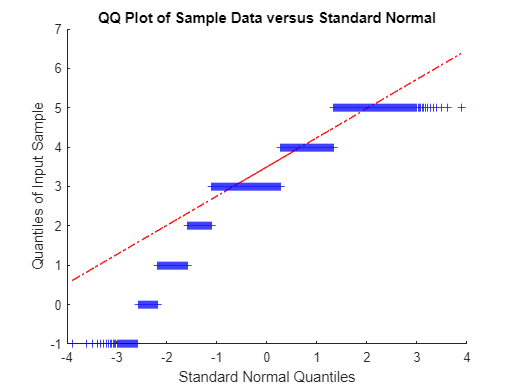

theta_hat = median(university_A)-median(university_B);
n = size(university_A,2);
R = 9999;
theta_repl= zeros(1, R);
rand('state', 1);
for i=1:R
    rs_indx_a = ceil(n*rand(1,n));
    rs_indx_b = ceil(n*rand(1,n));
    Y_boot_a = university_A(rs_indx_a);
    Y_boot_b = university_B(rs_indx_b);
    theta_repl(i) = median(Y_boot_a-Y_boot_b);
end
qqplot(theta_repl); % refusem normalitat.

%percentile-based conf intervals
alpha = 0.05;
theta_rep_sort = sort(theta_repl);
conf_interval = [2*theta_hat - theta_rep_sort(round((R)*(1-alpha/2))), 2*theta_hat-theta_rep_sort(round((R)*(alpha/2)));]

conf_interval =      3     7


b) Use bootstrap to test the relevant null hypothesis for this problem.

PROBLEM 2/3

a) with bootstrap-t confidence intervals

university_A = [10 9 8 10 8] % Fila 1 science score, Fila 2 Communication score

university_A =     10     9     8    10     8


university_B = [9 6 5 5 5]

university_B =      9     6     5     5     5


theta_hat = median(university_A)-median(university_B);
n = size(university_A,2);
R = 9999;
theta_repl= zeros(1, R);
Y_boot_a = zeros(R, n);
Y_boot_b = zeros(R, n);
rand('state', 1);
for i=1:R
    rs_indx_a = ceil(n*rand(1,n));
    rs_indx_b = ceil(n*rand(1,n));
    Y_boot_a(i,:) = university_A(rs_indx_a);
    Y_boot_b(i,:) = university_B(rs_indx_b);
    theta_repl(i) = median(Y_boot_a(i,:)-Y_boot_b(i,:));
end
qqplot(theta_repl); % refusem normalitat.

%bootstrap-t confidence intervals
theta_repl_boot = zeros(1,R);
for i=1:R
    rs_indx_a = ceil(n*rand(1,n));
    rs_indx_b = ceil(n*rand(1,n));
    Y_boot_boot_a = Y_boot_a(i, rs_indx_a);
    Y_boot_boot_b = Y_boot_b(i, rs_indx_b);
    theta_repl_boot(i) = median(Y_boot_boot_a-Y_boot_boot_b);
end
z = (theta_repl_boot - theta_hat)/std(theta_repl_boot);
z_sorted = sort(z);
tlow = z_sorted(round(alpha/2*R));
thigh = z_sorted(round((1-alpha/2)*R));
conf_interval = [theta_hat - thigh*std(theta_repl_boot), theta_hat - tlow * std(theta_repl_boot)]

conf_interval =      3     8


PROBLEM 13

a) Use bootstrapping to assess if the distribution of the sample kurtosis can be assumed normal. Clearly indicate your conclusion.

%X = SM22Lab3HeightandWeight{:,:};
%X(:,2) = X(:,2)/100;
%n = size(X, 1);
%B = 1e4;
%theta_rep = zeros(B, 1);
%for j = 1:B
%    rs_idx = ceil(n*rand(1,n));
%    X_boot = X(rs_idx,:); 
%    kurtosis_rep = kurtosis(X_boot);%Sample kurtosis of each columnn in X
%    theta_rep(j) = kurtosis_rep(1)/kurtosis_rep(2)^2;
%end
%histogram(theta_rep);
%hold on
%plot(theta_hat, 0, '*');
%hold off
%qqplot(theta_rep);


No es normal :D

b) Based on the bootstrap from (a), estimate the standard error and the bias of your estimator. 

%theta_hat = zeros(n,1);
%for i=1:n
%    theta_hat(i) = a(i)/b(i);
%end
%theta_hat
%kurtosis_ = kurtosis(theta_hat)
%theta_hat = kurtosis_(1)/kurtosis_(2)^2
%std_error = std(theta_rep)
%bias = mean(theta_rep) - theta_hat

c) Estimate a 95% confidence interval for the kurtosis using student’s t. Based on your analysis from (b), discuss whether this is likely to be accurate or not. 

%alpha = 0.05;
%theta_biasCorrected = 2*theta_hat-mean(theta_rep);
%conf_interval = [theta_biasCorrected-tinv(alpha/2, n-1)*std_error theta_biasCorrected+tinv(alpha/2, n-1)*std_error]

d) Compute a 95% confidence interval for the kurtosis using the percentiles of the bootstrap distribution.

PROBLEM 14

a) State the null and alternative hypotheses for this problem. 


$$\begin{array}{l}
H_0 :\mu_1 =\mu_2 \to \delta_0 =0\\
H_A :\mu_1 <\mu_2 
\end{array}$$


donde $\mu_i$ es el estimador de la media del lab "i". Y $\delta_0$ es la diferencia que hay entre los estimadores en la hipótesis nula. En este caso, como en la hipótesis nula los estimadores son iguales el valor de esta variable es 0.

b) Use bootstrapping to test the hypotheses defined in (a) at significance level α = 0.05. Report your estimated p-value and state your conclusion answering the research question.

x = SM22Lab3Marks{:,:};
d = x(:,2) - x(:,1);
d_H0 = d - mean(d);
theta_hat = mean(d)

theta_hat = 0.9969

theta_hat_H0 = mean(d_H0) % sempre serà 0, aixo es innecesari.

theta_hat_H0 = 1.9429e-16

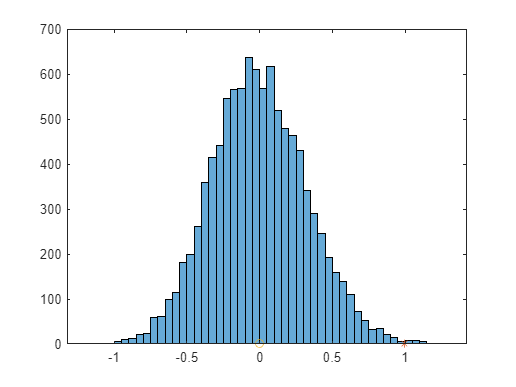

B = 1e4;
n = length(x);
theta_rep_h0 = zeros(B, 1);
%theta_rep = zeros(B, 1);
for j = 1:B
    rs_idx = ceil(n*rand(1,n));
    d_H0_boot= d_H0(rs_idx);
    theta_rep_h0(j) = mean(d_H0_boot);
    %d_boot= d(rs_idx);
    %theta_rep(j) = mean(d_boot);
end
% histogram(theta_rep);
histogram(theta_rep_h0);
hold on
plot(theta_hat,0,'*');
plot(theta_hat_H0, 0,'o');        %theta_hat_H0
hold off

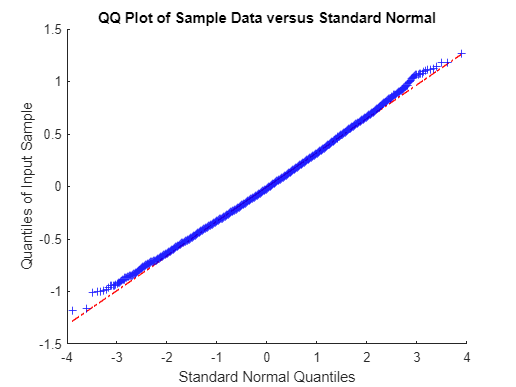

n_against_h0 = length(find(theta_rep_h0 >= theta_hat));
qqplot(theta_rep_h0);

p_value = n_against_h0/B %Reject

p_value = 0.0023

c) Use bootstrapping to compute a 95% confidence interval of the average difference between the marks of labs 1 and 2. Analyze whether the conclusion from this interval confirms or contradicts your conclusion from (b). 

alpha = 0.05;
% intervalo para theta_hat(x,y). Jo crec que realment el interval que ens
% demanen es aquest pero no esta centrat a theta_rep_h0 i crec q hauria
std_error = std(theta_rep_h0);
theta_biasCorrected = 2*theta_hat-mean(theta_rep_h0);
conf_interval = [theta_biasCorrected-tinv(alpha/2, n-1)*std_error theta_biasCorrected+tinv(alpha/2, n-1)*std_error]

conf_interval =     2.6635    1.3351



%  segons el que ell ens ha dit: es a dir calculant l'interval de confiança per theta_hat_H0
% O sigui no fa falta corregir el bias?
std_error_H0 = std(theta_rep_h0);
conf_interval_H0 = [theta_hat_H0 - tinv(alpha/2, n-1)*std_error_H0 theta_hat_H0 + tinv(alpha/2, n-1)*std_error_H0]

conf_interval_H0 =     0.6642   -0.6642


Com l'interval és "petit" els nostres resultats són bastant acurats. És a dir, el que hem obtingut a b és bastant acurat.

PROBLEM 15

a) State the null and alternative hypotheses for this problem. 


$$\begin{array}{l}
H_0 =\rho \left(x_1 ,x_2 \right)=\mathrm{correlation}\;\mathrm{between}\;x_1 \;\mathrm{and}\;x_2 =0\\
H_A =\rho \left(x_1 ,x_2 \right)\not= 0
\end{array}$$


b) Use bootstrapping to test the hypotheses defined in (a) at significance level α = 0.05. Report your estimated p-value and state your conclusion answering the research question.

x = SM22Lab3Baseball{:,:};
n = length(x);
theta_hat = corr(x(:,1), x(:,2))

theta_hat = 0.1068

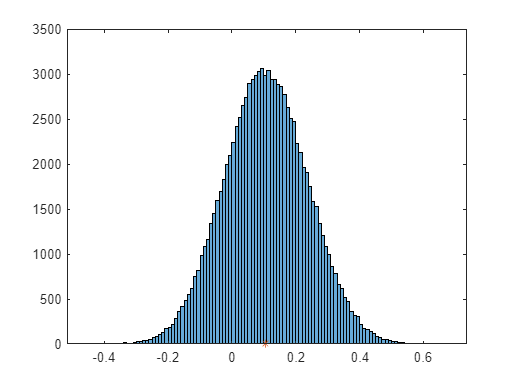

B = 1e5;
for j = 1:B
    rs_idx = ceil(n*rand(1,n));
    x_boot= x(rs_idx,:);
    theta_rep(j) = corr(x_boot(:,1), x_boot(:,2));
end 
histogram(theta_rep)
hold on
plot(theta_hat, 0,'*');            % no se'm dibuixa bé
hold off

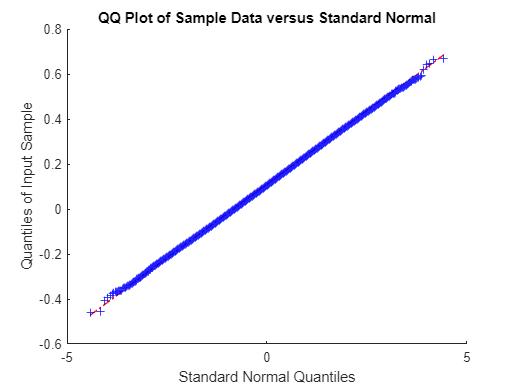

n_against_h0 = length(find(theta_rep >= theta_hat));
qqplot(theta_rep)

p_value = n_against_h0/B %Can't reject perque no es proper a 0

p_value = 0.4978

c) Use bootstrapping to compute a 95% confidence interval of the correlation coefficient between salaries and batting averages. Analyze whether the conclusion from this interval confirms or contradicts your conclusion from (b). 

alpha = 0.05;
std_error = std(theta_rep);
theta_biasCorrected = 2*theta_hat-mean(theta_rep);
conf_interval = [theta_biasCorrected-tinv(alpha/2, n-1)*std_error theta_biasCorrected+tinv(alpha/2, n-1)*std_error]

conf_interval =     0.3683   -0.1553


Theta_hat is in interval so we can't reject H0 Which means there is a linear relationship between salary and performance.

PROBLEM 16

a) Assess whether these two random samples seem to come from normal distributions. 

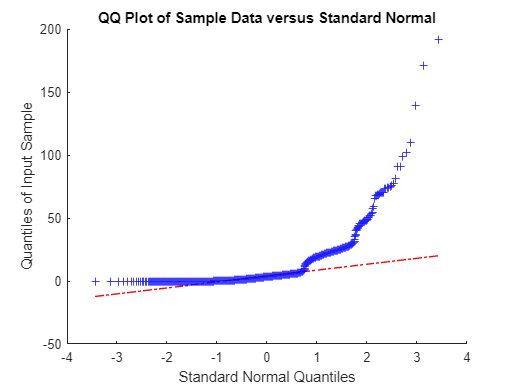

x1 = SM22Lab3ILEC1{:,:};
x2 = SM22Lab3ILEC2{:,:};
qqplot(x1);

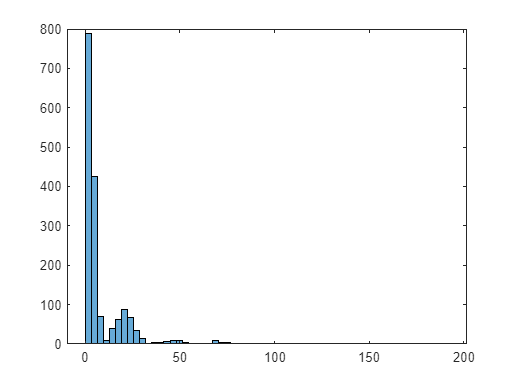

histogram(x1, 60);

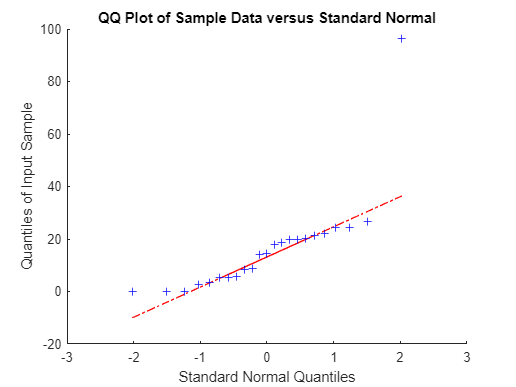

qqplot(x2);

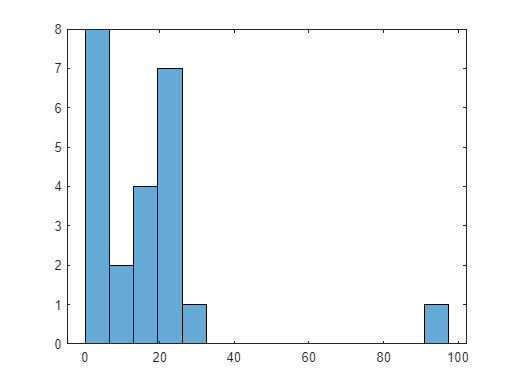

histogram(x2, 15);

no, ninguno.

b) Use bootstrapping to generate a simulated population of random resamples that allows you to inspect the distribution of the statistic t = $\bar{x_1 }$ − $\bar{x_2 }$. 

theta_hat = mean(x1)-mean(x2)

theta_hat = -8.0975

B = 1e4;
n1 = length(x1);
n2 = length(x2);
for j=1:B
    rs_indx_1 = ceil(n1*rand(1,n1));
    rs_indx_2 = ceil(n2*rand(1,n2));
    x1_boot = x1(rs_indx_1);
    x2_boot = x2(rs_indx_2);
    theta_rep(j) = mean(x1_boot)-mean(x2_boot);
end

c) Estimate the bias of t = $\bar{x_1 }$ − $\bar{x_2 }$. 

bias = mean(theta_rep) - theta_hat

bias = 7.3842

d) Compute a 95% confidence interval for t based on the percentiles of the bootstrap distribution. Based on the analysis from (a) and (b) discuss whether this interval seems appropriate. 

alpha = 0.05;
theta_rep_sort = sort(theta_rep);
conf_interval = [2*theta_hat - theta_rep_sort(round((B)*(1-alpha/2))), 2*theta_hat-theta_rep_sort(round((B)*(alpha/2)))]

conf_interval =   -14.4841    0.8458


intervalo jodidamente grande, rechazamos.

e) Based on your answers to (b) and (d), what can you conclude about the statement following statement: "repair times for ILEC customers are significantly smaller than repair times for CLEC customers".

Pocas muestras de CLEC, rechazamos por los interevalos grandes por lo cual no tendran mismo tiempo de reparación, no sabemos si más o menos.

Y esas cositas...

PROBLEM 17

Analyze the data carefully and justify the method chosen to estimate the requested interval.

X = SM22Lab33D{:,:};
n = length(X);
B = 1e4;
theta_rep = zeros(B, 1);
cov_matrix = cov(X);
theta_hat = cov_matrix(1,1)/cov_matrix(2,2)

theta_hat = 1.2929

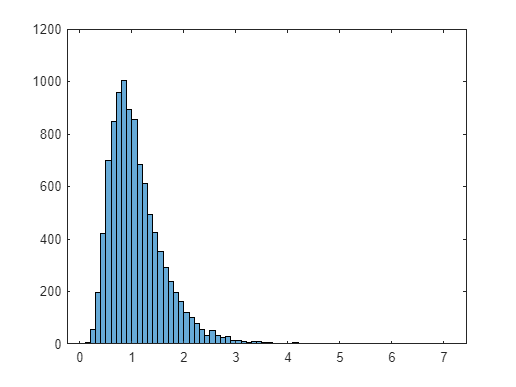

for j = 1:B
    rs_idx = ceil(n*rand(1,n));
    X_boot = X(:,rs_idx); 
    cov_matrix_boot = cov(X_boot);
    theta_rep(j) = cov_matrix_boot(1,1)/cov_matrix_boot(2,2);
end
histogram(theta_rep)

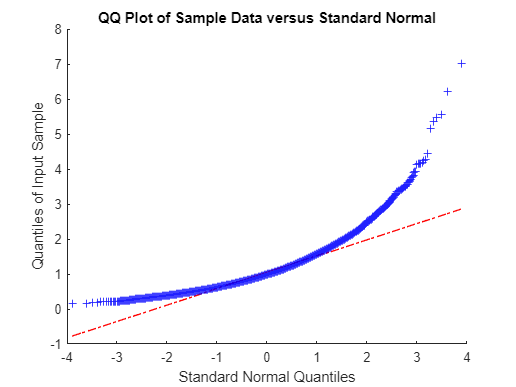

qqplot(theta_rep)

Usamos percentiles pq no es normal

alpha = 0.05;
theta_rep_sort = sort(theta_rep);
conf_interval = [2*theta_hat - theta_rep_sort(round((B)*(1-alpha/2))), 2*theta_hat-theta_rep_sort(round((B)*(alpha/2)))]

conf_interval =     0.1620    2.1870


No se que conclusión sacar, le preguntaria la verdad.